%Made by Kai Brown and Kevin Pogrund
%        BRWKAI001 and PGRKEV001
%Assume alpha is the top left corner of the triangle
disp("Question 1");

Question 1


disp("a)");

a)



syms m L alpha dalpha ddalpha
%DOF
%1. z1 = 0
%2. z2 = 0
%3. x1 = 0
%4.  y2 = 0
%5.  y1^2 +x2^2 = L
% dof = 3x2 - 5
q = [alpha];
dq = [dalpha];

%position
p1 = [0; L*cos(alpha)];
p2 = [L*sin(alpha); 0];

%Kinematics 
v1 = simplify(jacobian(p1,q)*dq);
v2 = simplify(jacobian(p2,q)*dq);

% Body Energy
% Kinetic
T = 0.5*m*transpose(v1)*v1+0.5*m*transpose(v2)*v2;
T = simplify(T);
% Potential
V = m*g*p1(2);

%Lagrange 
Lagrange = T - V;
Lagrange = simplify(Lagrange);

%EOM
dLalpha=simplify(diff(Lagrange,alpha)); %dL/alpha
dLdaplha=simplify(diff(Lagrange,dalpha));%dL/alphadot
ddtdLdalpha=simplify(diff(dLdaplha,dalpha)*ddalpha);%d/dt dL/alphadot

%***************
ddalpha = solve(ddtdLdalpha-dLalpha, ddalpha)

$$ddalpha = \frac{981\,\sin\left(\alpha \right)}{100\,L}$$

disp("b)")

b)


L = 0.5;
m = 1;
[t, y] = simulate_twoMassSliding(@f, [0; 10], [15*pi/180; 0])

t =          0
    0.0013
    0.0025
    0.0037
    0.0050
    0.0063
    0.0075
    0.0088
    0.0100
    0.0112


y =     0.2618         0
    0.2682         0
    0.2748         0
    0.2815         0
    0.2884         0
    0.2955         0
    0.3027         0
    0.3101         0
    0.3177         0
    0.3254         0


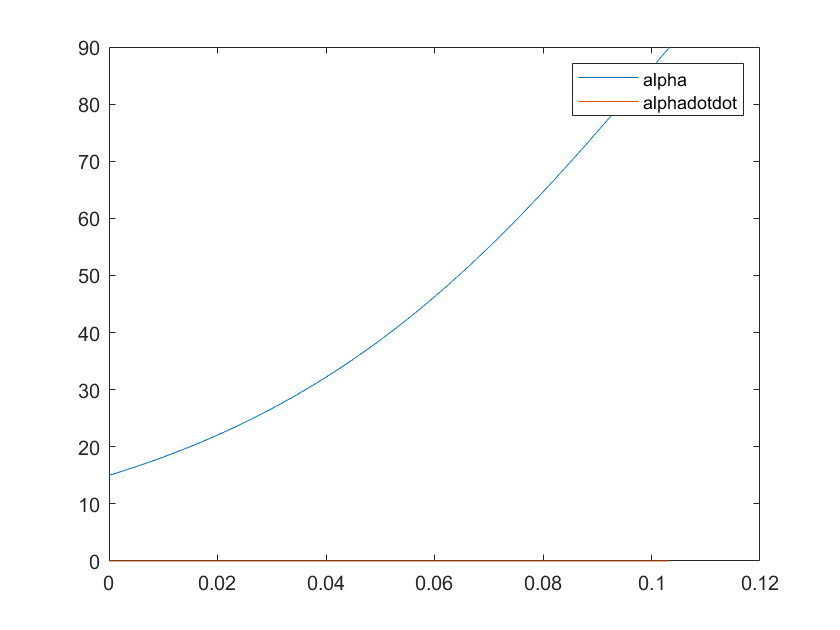


%fix plot
figure()
plot(t, y*180/pi)
legend('alpha', 'alphadotdot')

disp("c)")

c)


%{
%% Anim_twoMassSliding
close all;
disp('This runs slightly slower so that you can see the animation')
disp('Make sure the rod length L is defined in your workspace')

%% Positions
%tempAlpha = alpha.signals.values; % uncomment if you simulated in Simulink
tempAlpha = y(:, 1);
pos1 = [zeros(length(tempAlpha),1), L.*cos(tempAlpha)]; % [x, y] positions
pos2 = [L.*sin(tempAlpha), zeros(length(tempAlpha),1)];

%% Create Figure Handles
figure
axis([0 0.6 0 0.6])
grid on
hold on;

% The rod
h1 = line('Color', 'b', 'LineWidth', 1);

% Mass plots
p1 = plot(pos1(1,1),pos1(1,2),'o','MarkerFaceColor','red','MarkerSize',12);
p2 = plot(pos2(1,1),pos2(1,2),'o','MarkerFaceColor','red','MarkerSize',12);

% general plot setup
xlabel({'X Position (m)'},'FontSize',14,'FontName','AvantGarde');
ylabel({'Y Position (m)'},'FontSize',14,'FontName','AvantGarde');

title({'Two Sliding Masses'},'FontWeight','bold','FontSize',20,...
    'FontName','AvantGarde');

%% Update the rod and masses in the plot in a loop
for i = 1:length(tempAlpha)
    % Rod
    % have to do the line below instead of h1.XData = [pos1(i,1), pos2(i,1)]
    % to maintain octave compatibilty, for whatever reason
    set(h1, 'XData', [pos1(i,1), pos2(i,1)]);
    set(h1, 'YData', [pos1(i,2), pos2(i,2)]);

    % Mass Positions
    set(p1, 'XData', pos1(i,1));
    set(p1, 'YData', pos1(i,2));
    set(p2, 'XData', pos2(i,1));
    set(p2, 'YData', pos2(i,2));
    
    pause(0.1);  % the time per loop is (calculation/render time) + (pause)
                 % this doesn't need to be done properly -- we'll work on
                 % that in part 2 of this prac
    drawnow 
   
    xlim('manual')
    ylim('manual')
end
%}

Question 2


a)


function [t, y] = simulate_twoMassSliding(func, tspan, y0)
    options = odeset('Events', @eventFcn, 'MaxStep', 0.005);

    [t,y,~,~,~] = ode45(func, tspan, y0, options);
end

function [position,isterminal,direction] = eventFcn(~, y)
    position = y(1) - pi/2; % The value that we want to be zero
    isterminal = 1;  % Halt integration
    direction = 0;   % The zero can be approached from either direction
end

function y = f(t, angle)
   L = 0.5;
   m = 1;
   y = 9.81*sin(angle)/L;
end
